# Regenerator

clear;
% file = "me.wav";
% file = "../audio/sax.wav";
file = "recr.wav";
[X,Fs] = audioread(file); 
X = X(:, 1);
% X = X(1:18000);
% X = X(1:end);
T = 1 / Fs;
L = length(X);
t = (0:L-1)*T;

size(X)

ans =        44100           1





% Fs = 48000;            % Sampling frequency                    
% T = 1/Fs;             % Sampling period       
% L = 57344;             % Length of signal
% t = (0:L-1)*T;        % Time vector
% S = 0.8 + 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
% X = S; %+ 2*randn(size(t));

% Fs = 80;            % Sampling frequency                    
% % T = 1/Fs;             % Sampling period       
% L = 8;             % Length of signal
% t = (0:L-1)/Fs        % Time vector
% S = [300 1 4 1 5 9 2 6];
% X = S; %+ 2*randn(size(t));

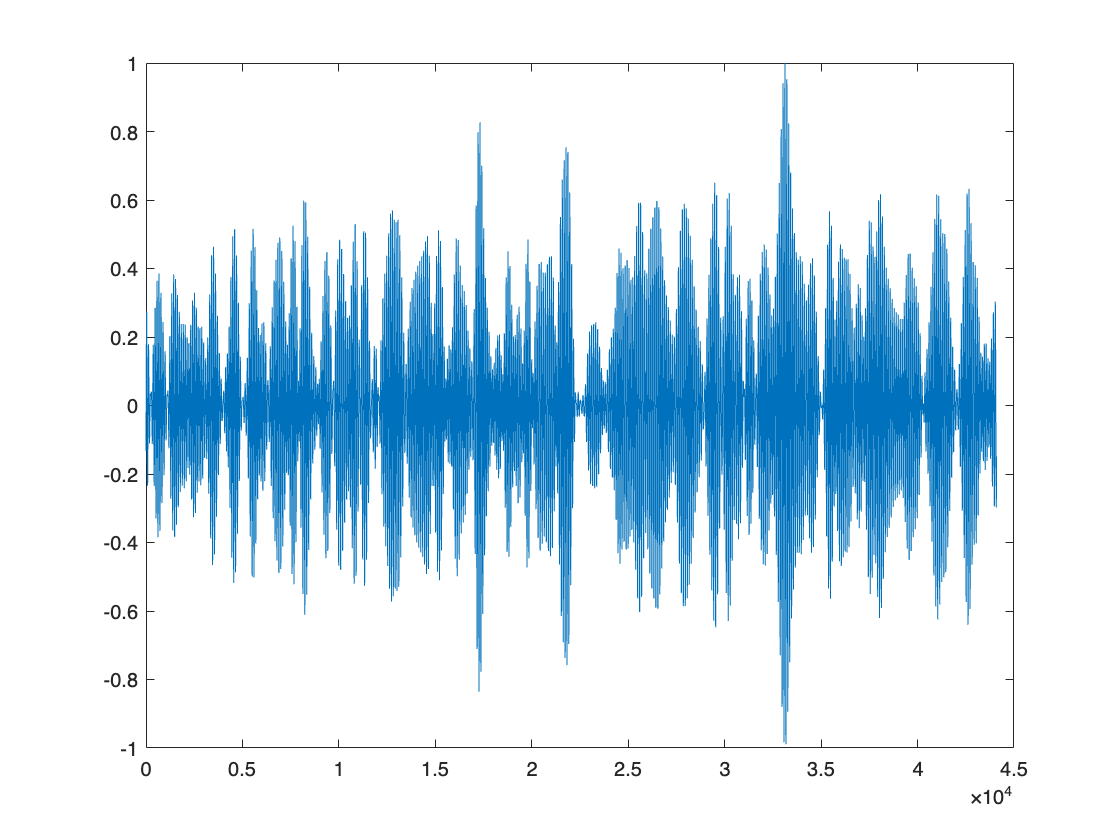

plot(Fs*t,X)

% return

% xlim([0 end])

Compute the Fourier transform of the signal. 

Y = fft(X);

Because Fourier transforms involve complex numbers, plot the complex magnitude of the `fft` spectrum.

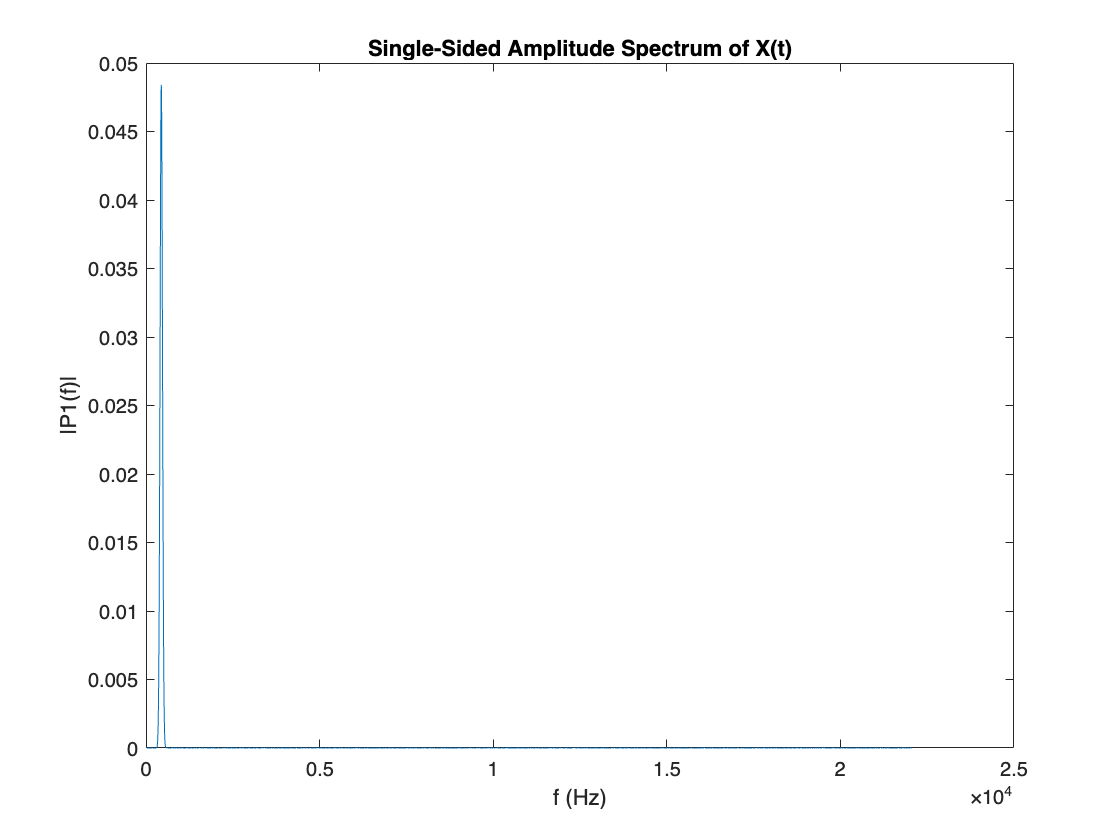

% plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)
% title("Complex Magnitude of fft Spectrum")
% xlabel("f (Hz)")
% ylabel("|fft(X)|")
% plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)),"LineWidth",3)
% title("fft Spectrum in the Positive and Negative Frequencies")
% xlabel("f (Hz)")
% ylabel("|fft(X)|")
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
P1_a = angle(Y);
P1_a = P1_a(1:L/2+1);
f = Fs/L*(0:(L/2));
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

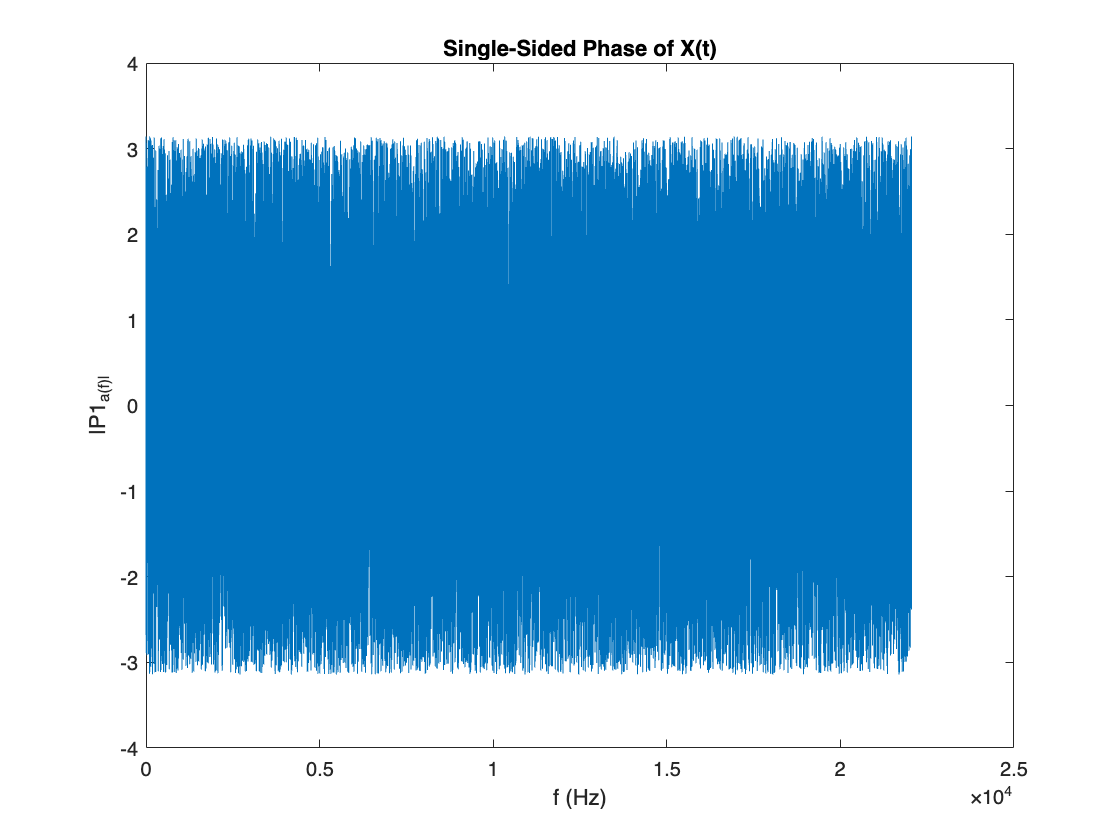

% xlim([0 2000])
% sort(P1, 'descend');
f = Fs/L*(0:(L/2));
plot(f,P1_a) %"LineWidth",3) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")
ylabel("|P1_a(f)|")

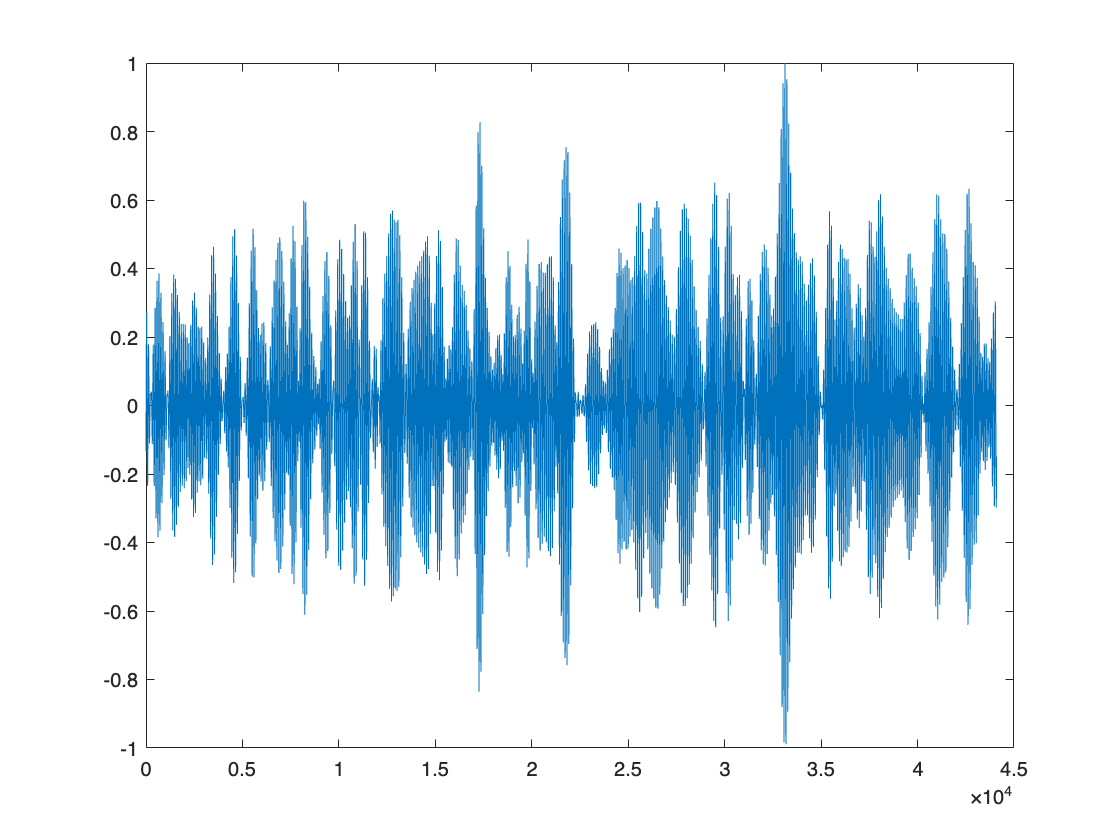


% xlim([0 5630])
recs = zeros([1, L]);
for i = 0:(L/2) % L/2
    mag = abs(Y(i+1));
    phase = angle(Y(i+1));
    add = 2*mag/L * cos(2*pi*t*Fs/L*i + 1*phase);
    if i == 0 || i == L/2
        add = add / 2;
    end
    recs = recs + add;
end
plot(Fs*t,recs);



% recs - X.';

% recs =  (1*abs(Y(1))/8)*cos(0*pi*t + angle(Y(1))) + ...
%         (2*abs(Y(2))/8)*cos(2*pi*t + angle(Y(2))) + ...
%         (2*abs(Y(3))/8)*cos(4*pi*t + angle(Y(3))) + ...
%         (2*abs(Y(4))/8)*cos(6*pi*t + angle(Y(4))) + ...
%         (1*abs(Y(5))/8)*cos(8*pi*t + angle(Y(5)));
% plot(Fs*t,recs)

audiowrite("recr.wav",recs,Fs)